**Pandemic fatigue impedes mitigation of COVID-19 in Hong Kong**

Codes by: Dr. Zhanwei Du 

Location: HKU

Date: Sepetember 20, 2022

Licence: GNU General Public License v3.0 ([GPL3](https://link.segmentfault.com/?enc=F8eFgPWEFfpOCjwTltrWWQ%3D%3D.FbySfqMMTRW07%2B7QgXT16IQQsnQO6%2FOFvx5hjIb4%2FAIvSOH%2FtpYp0QwJ3crDZDiK))

Random Seed for repeating simulations

rng(100);

Take the fourth wave as a example here

WaveInd = 4; % 4 for the third wave; and 3 for the third wave;

## Load data

% HK reported cases
Incidence_data = readtable('time_series_covid19_confirmed_global_hk_zw.xlsx');
Observation = table2array(Incidence_data(:,3));
Observation = Observation';

% Fatigue_PM3n.xlsx has format: Date, Percentage of people avoiding social gathering
% We may be not possible to share data to the public. If it is true, a array with 364 numbers are generated by random for running.
if exist('Fatigue_PM3n.xlsx')
    Fatigue_PM3n = readtable('Fatigue_PM3n.xlsx');
    Fatigue_PM3n = table2array(Fatigue_PM3n(:,2));
    Fatigue_PM3n = Fatigue_PM3n';
else
    Fatigue_PM3n = 100*random(1, 364);
end

% Normalize the Fatigue_PM3n to [0,1]
Fatigue_PM3n = (Fatigue_PM3n-min(Fatigue_PM3n))/(max(Fatigue_PM3n)-min(Fatigue_PM3n));
% cut Observation to length with Fatigue_PM3n
Observation = Observation(1,(15+9+1):end);

## Filter data to waves in HK

% 3 July to 26 August 2020 and 30 October 2020 to 31 January 2021
% Outbreak 3: 141-195th row in data table
% Outbreak 4: 278-353th row in data table
if WaveInd == 3; Time_length_begin = 141-1; Time_length_end = 195-1; end
if WaveInd == 4; Time_length_begin = 260-1;  Time_length_end = 353-1; end
Observation = Observation(1, Time_length_begin:Time_length_end);
Fatigue_PM3n = Fatigue_PM3n(1,(Time_length_begin-5):(Time_length_end-5));

## EAKF algorithm and Epidemic model 

initial settings

Motivated by prious studies of Dr. Sen Pei.

More details of this algorithm in ref.: 

EAKF_initialize;

## EAKF running

for k = 2:T
    pf.k = k;
    param.Fatigue_PM3n_k = Fatigue_PM3n(:,k);
    param.oev = sqrt(  mean( Observation(:,max(k-3,1):k-1) )^2/oev5 );
    [xh(:,k), pf] = particle_filter(sys, Observation(:,k), pf, 'multinomial_resampling',param);
    yh(:,k) = obs(k, xh(:,k), 0);
end

## Plot

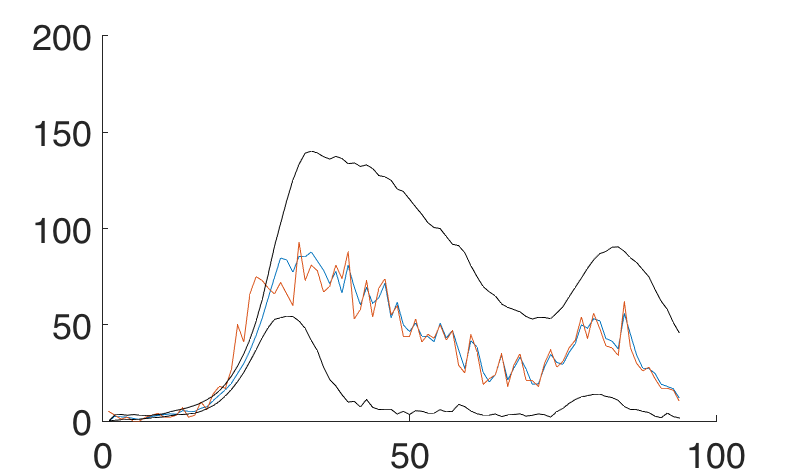

figure;
hold on
plot(xh(8,:))
plot(Observation);
temp_xh = (quantile( reshape( pf.particles(8, :, :), size( pf.particles,2), size(pf.particles(8, :, :),3)), [0.5, 0.025, 0.975]) );

for i=1:size(temp_xh,1)
    temp_xh(i,:) = smooth(temp_xh(i,:),7);
end

plot(temp_xh(2:3, :)', 'k')
ylim([0 200])
set(gca, 'fontsize', 20)
set(gcf,'PaperPositionMode', 'auto')   % Use screen size
set(gcf,'position',[0,0, 100*5, 60*5]);